# Example 2.7: Pdf and Cdf of Binomial RV

Note: this script reproduces Example 2.7 (Section 2.1.4) of **Statistics for Chemical Engineers**: the binomial RV, and its relation to the hypergeometric RV. Victor Z UW-Madison, 2020 pdf and cdf of a binomial RV

clc; clear all; close all hidden;

## Pdf and cdf

pdf

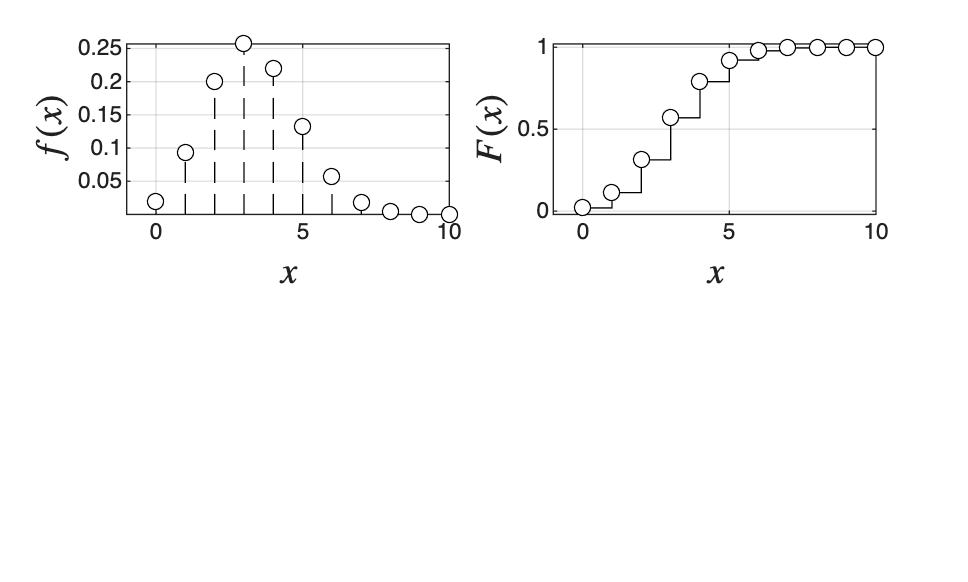

n=10;
p=0.3;
x=0:1:n;
n=length(x);

f=binopdf(x,n,p); %matlab built-in function
F=binocdf(x,n,p); %matlab built-in function

figure(1)

% visualize pdf and cdf
subplot(2,2,1)
for j=1:n
    plot(x(j)*ones(100,1),linspace(0,f(j),100),'black--')
    hold on
end
scatter(x,f,'MarkerFaceColor','w','MarkerEdgeColor','black')
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
axis([min(x)-1 10 min(f) max(f)])
subplot(2,2,2)
stairs(x,F,'black-')
hold on
for j=1:n
    scatter(x(j),F(j),'MarkerFaceColor','w','MarkerEdgeColor','black')
    hold on
end
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
axis([min(x)-1 10 -0.02 1.02])

## Different values of p

compare for different p

 p=[0.95 0.75 0.5];
color=["black","black","black"];
marker=["o-","x-","d-"];

subplot(2,2,3)
for k=1:length(p)
plot(x,binopdf(x,n,p(k)),marker(k),'MarkerFaceColor','w','MarkerEdgeColor',color(k),'Color',color(k))
hold on
end
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
lgd=legend('$p=0.95$','$p=0.75$','$p=0.50$','Interpreter','latex','location','northwest')

lgd =   Legend ($p=0.95$, $p=0.75$, $p=0.50$) with properties:

         String: {'$p=0.95$'  '$p=0.75$'  '$p=0.50$'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 7.6500e+00
       Position: [1.4328e-01 3.1017e-01 1.5884e-01 1.2154e-01]
          Units: 'normalized'

  Show all properties

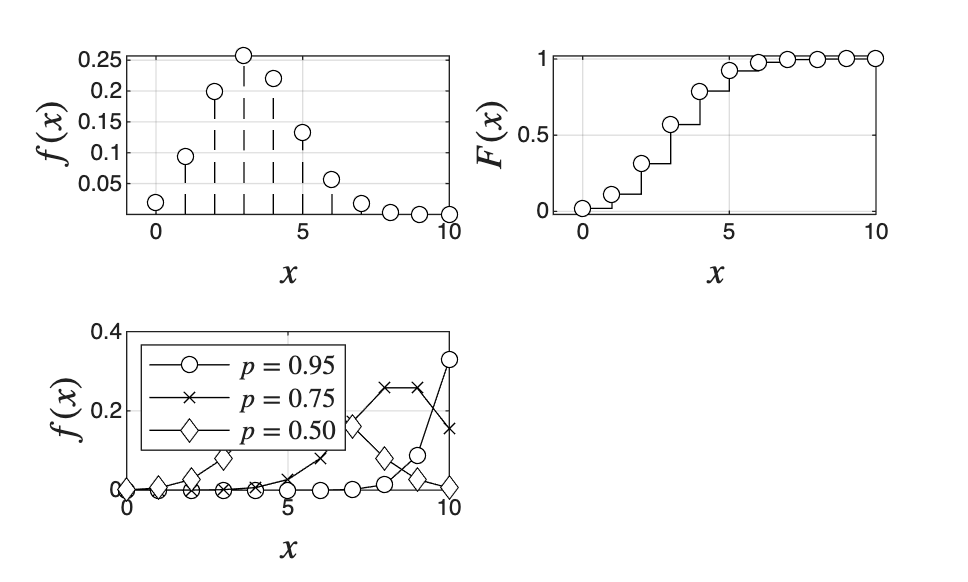

lgd.FontSize = 10;

title('')

## Hypergeometric vs. binomial

demonstrate that hypergeometric converges to binomial

subplot(2,2,4)
p=0.25

p =    2.5000e-01

n=10;
x=0:1:n;
n=length(x);
N=1000

N =         1000

for j=1:length(N)
Ny=round(p*N(j));
xs=max(n+Ny-N(j),0):1:min(n,Ny);
plot(xs,hygepdf(xs,N(j),Ny,n),'black--','LineWidth',0.5)
hold on
end
grid on
plot(x,binopdf(x,n,p),'blacko','MarkerFaceColor','w','MarkerEdgeColor','black','Color','black','LineWidth',1.5)
lgd=legend('$H(1000,n,p)$','$Bi(n,p)$','Interpreter','latex','location','northeast')

lgd =   Legend ($H(1000,n,p)$, $Bi(n,p)$) with properties:

         String: {'$H(1000,n,p)$'  '$Bi(n,p)$'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 7.6500e+00
       Position: [6.9880e-01 3.4723e-01 1.9244e-01 8.4486e-02]
          Units: 'normalized'

  Show all properties

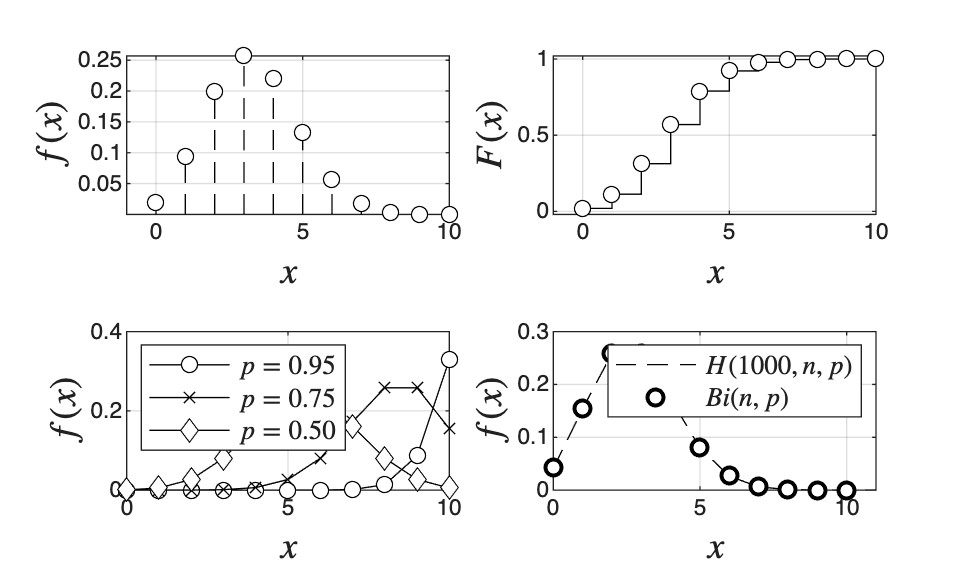

lgd.FontSize = 10;
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
print -depsc ch2_pdfcdfbinomial.eps

## Note

As in the book, the hypergeometric pdf for a large population (N_t = 1000) is nearly identical to the binomial pdf: the hypergeometric RV converges to a binomial RV.